# Computation and fitting of the Ogive function (ideal case)

## Load the data set 

The data loaded are single time series of the alongwind ($$u$$) and vertical ($w$) velocity components. 

clearvars;close all;clc;
load('data.mat','t','u','w','z','u_star')

## Compute the auto and cross-point power spectral densities

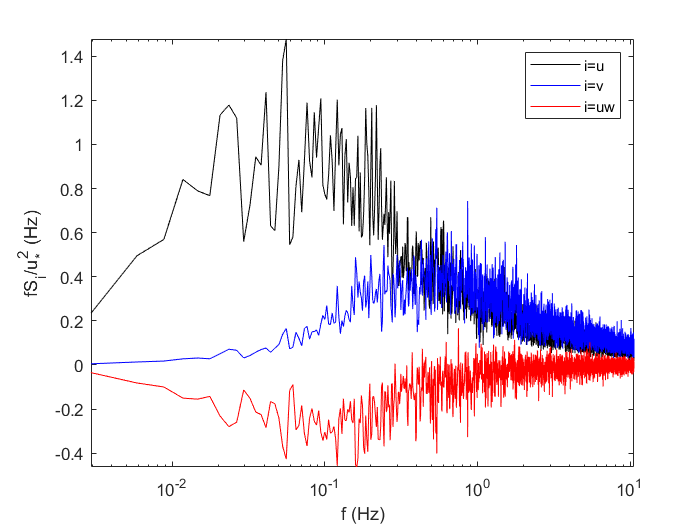

N=numel(t);
dt = median(diff(t));  % time-step
fs = 1/dt; % sampling frequency
Nblock = 6; % overlapping segments for Welch's algorithm
Nwin = round(N/Nblock); % Number of point per window
meanU = nanmean(u); % mean wind speed

% Compute the friction velocity with the traditional eddy-covariance method
uS1 = sqrt(-nanmean(detrend(u).*detrend(w)));

% Plot Power auto and cross-spectral densities of velocity
[Su,f]=pwelch(detrend(u),Nwin,round(Nwin/2),Nwin,fs);
[Sw,~]=pwelch(detrend(w),Nwin,round(Nwin/2),Nwin,fs);
[Suw,~] = cpsd(detrend(u),detrend(w),Nwin,round(Nwin/2),Nwin,fs);
Co = real(Suw); % Real part of the corss-spectral densities
%Normalized the PSD and CPSDs
Su = f.*Su./u_star.^2;
Sw = f.*Sw./u_star.^2;
Co = f.*Co./u_star.^2;
fr0 = z./mean(u).*f;

clf;close all;
figure
semilogx(fr0,Su,'k',fr0,Sw,'b',fr0,Co,'r')
hold on; box on;
% hold on
% plot([1 10],0.3*[1 10].^(-2/3),'m')
xlabel('f (Hz)')
ylabel('fS_i/u^2_* (Hz)')
set(gcf,'color','w')
legend('i=u','i=v','i=uw')
axis tight

## Compute the ogive function

[Og,fOg] = ogiveFun(f,real(Suw));

## Fit the Ogive function using a semi-empirical model

[Og1,fOg1,uS2] = fitOgive(fOg,Og,z,meanU,'fmin',1e-3,'fmax',fs/3);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         12.4562                          53.1
     1          6         2.78838       0.775093           20.4      
     2          9       0.0994604       0.295733           2.82      
     3         12       0.0151947      0.0362783          0.115      
     4         15       0.0149555      0.0134261       0.000484      
     5         18       0.0149555    6.80516e-05       9.46e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the selected value of the 


fprintf(['<u''w''> estimated with Ogive method is ',num2str(uS2,3),' m/s \n'])

<u'w'> estimated with Ogive method is 1.02 m/s 


fprintf(['<u''w''>  estimated with traditional eddy-covariance method is ', ...
    num2str(uS1,3),' m/s \n'])

<u'w'>  estimated with traditional eddy-covariance method is 1.02 m/s 


## Compare the Fitted and computed SQRT of the ogive functions

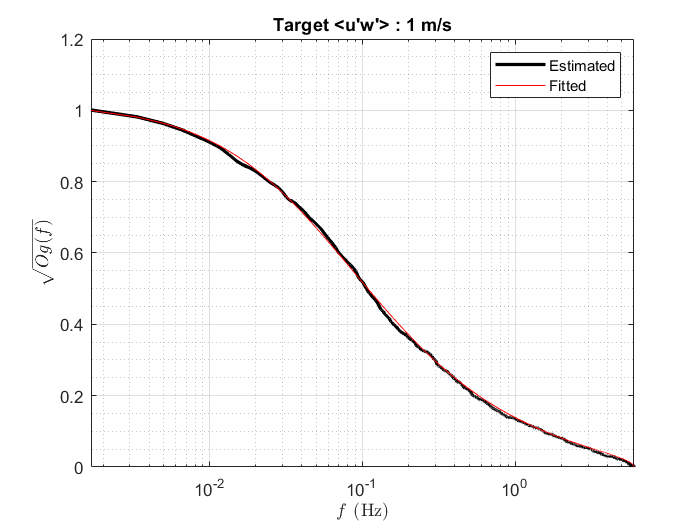

clf;close all;
figure
semilogx(fOg,sqrt(abs(Og)),'k','linewidth',2);
hold on
semilogx(fOg1,sqrt(abs(Og1)),'r');
xlim([Nblock/t(end), fs/2]);
ylabel('$\sqrt{Og(f)}$','interpreter','latex')
xlabel('$f$ (Hz)','interpreter','latex')
grid on; grid minor
legend('Estimated','Fitted')
title(['Target <u''w''> : 1 m/s'])
set(gcf,'color','w')

## How long is long enough according to the fitted Ogive function ?

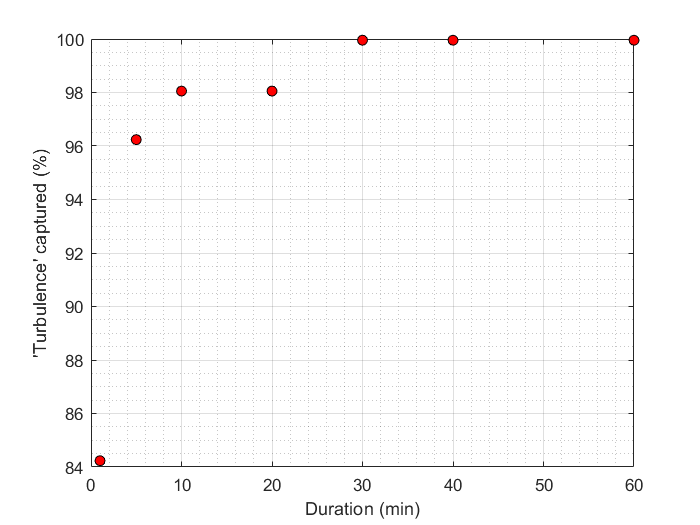

Duration = [1 5 10 20 30 40 60]; % Duration in minutes
PercTurb = zeros(1,numel(Duration)); % percentage of turbulence captured by a given averaging time
for ii=1:numel(Duration)
    [~, indF] = min(abs(1/(60*Duration(ii))-fOg1));
    PercTurb(ii) = 100*abs(sqrt(abs(Og1(indF)))./uS1);
end

figure
plot(Duration,PercTurb,'ko','markerfacecolor','r');
xlabel('Duration (min)')
ylabel('''Turbulence'' captured (%)')
% ylim([80 100])
grid on;
grid minor
set(gcf,'color','w')

## Case of a low sampling frequency

The extrapolation at high frequency is done assuming the behaviour of the ogive at high-frequencies is known. Whereas the direct computation of the covariance leads to an underestimated friction velocity, the use of a fitted ogive circumvents the problem of undersampling.

N=numel(t);
dt = median(diff(t));  % time-step
fs = 1/dt; % sampling frequency
Nblock = 10; % overlapping segments for Welch's algorithm

filterOrder = 100;
coeffDecimate = 100;
u1 = decimate(u,coeffDecimate,filterOrder,'fir');
w1 = decimate(w,coeffDecimate,filterOrder,'fir');


newFs = fs/coeffDecimate;


Nwin = round(numel(u1)/Nblock); % Number of point per window
meanU = nanmean(u1); % mean wind speed

% underestimated friction velocity
uS1_underestimated = sqrt(-nanmean(detrend(u1).*detrend(w1)));

% Plot Power auto and cross-spectral densities of velocity
[Su1,f]=pwelch(detrend(u1),Nwin,round(Nwin/2),Nwin,newFs);
[Sw1,~]=pwelch(detrend(w1),Nwin,round(Nwin/2),Nwin,newFs);
[Suw1,~] = cpsd(detrend(u1),detrend(w1),Nwin,round(Nwin/2),Nwin,newFs);


[Og,fOg] = ogiveFun(f,real(Suw1));
[Og1,fOg1,uS2] = fitOgive(fOg,Og,z,meanU,'fmin',1e-3,'fmax',newFs);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3        0.993286                          4.27
     1          6        0.148548        1.07452           1.25      
     2          9      0.00522896        0.77985          0.114      
     3         12      0.00233243       0.531373         0.0469      
     4         15      0.00216826       0.247824         0.0141      
     5         18      0.00216442     0.00709597       3.71e-05      
     6         21      0.00216442    0.000718106       2.79e-07      

Local minimum found.

Optimization completed because the size of the gradient is less than
the selected value of the 


fprintf(['Undersampled <u''w''> estimated with fitted Ogive is ',num2str(uS2,3),' m/s \n'])

Undersampled <u'w'> estimated with fitted Ogive is 1.03 m/s 


fprintf(['Undersampled <u''w''>  estimated with eddy-covariance method is ', ...
    num2str(uS1_underestimated,3),' m/s \n'])

Undersampled <u'w'>  estimated with eddy-covariance method is 0.815 m/s 
